IP = '192.168.0.200';

% Setup connection to AMC
amc = AMC_connect(IP);

Attocube motors connected


[errNo, status] = control_getControlOutput(amc, axis);
disp(status);

    {[1]}



axis = 2; % Axis Z
control_setControlOutput(amc, axis, true);

[errNo, sensor_status] = status_getOlStatus(amc, axis);
disp(sensor_status);

     3



% for small number below 400 mV, can't read DC value
[errNo, pos1, pos2, pos3, val1, val2, val3] = control_getPositionsAndVoltages(amc) 

errNo = 0

pos1 = 2.8653e+06

pos2 = 3.4856e+06

pos3 = 3.9968e+06

val1 = 701.6960

val2 = 3.0248e+04

val3 = 2.5087e+04

amplitude_mv = 0;
% also changes in real time, does not show up though if V < 1V
control_setControlFixOutputVoltage(amc, axis, amplitude_mv);


[errNo, amplitude_mv] = control_getControlFixOutputVoltage(amc, axis) 

Unrecognized field name "result".

Error in control_getControlFixOutputVoltage (line 17)
errNo = data.result (1);

amplitude = 60000

amplitude = 60000

% changes in real time
control_setControlAmplitude(amc, axis, amplitude) 

ans = 0

freq = 100000

freq = 100000

control_setControlFrequency(amc, axis, freq)

ans = 0

[errNo, position] = move_getControlTargetPosition(amc, axis) 

errNo = 0

position = 2876200

[errNo, position] = move_getPosition(amc, axis)

errNo = 0

position = 2.8653e+06

% doesn't work so well??? the step is not moved by too much 
move_performNSteps(amc, axis, true);

% this seems about the same. just use this one
move_setSingleStep(amc, axis, false);

move_setNSteps(amc, axis, true, 3);

[errNo, connected] = status_getStatusConnected(amc, axis)

clear amc;

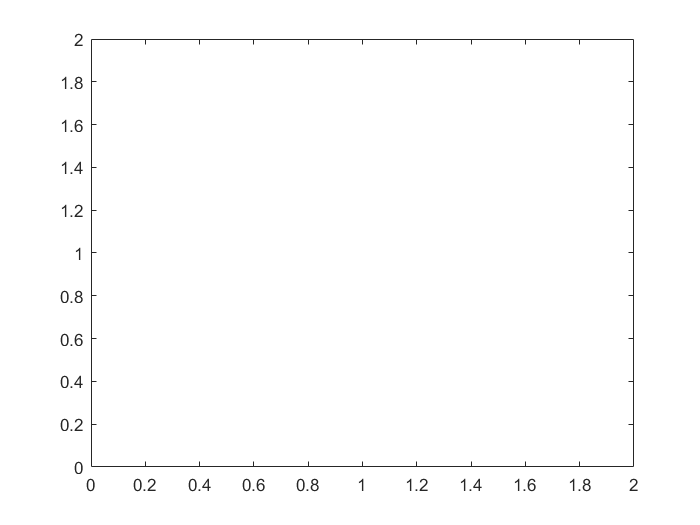

lst = {};
lst{end + 1} = 1;
x = 1 : numel(lst);

plot(x, cell2mat(lst));

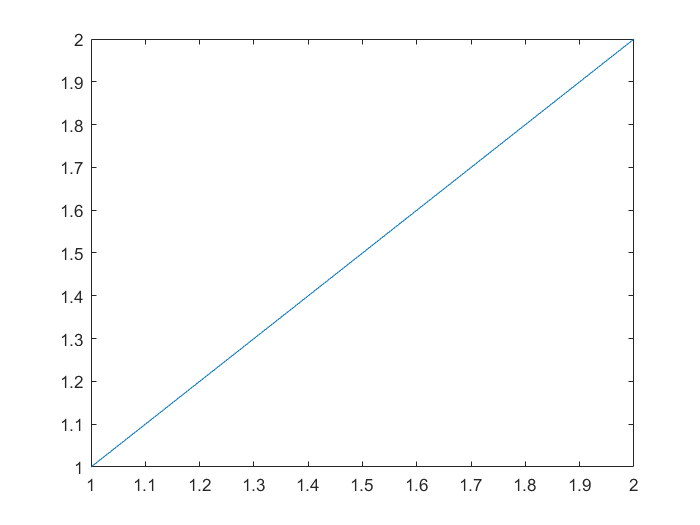


lst{end + 1} = 2;
x = 1 : numel(lst);

plot(x, cell2mat(lst));

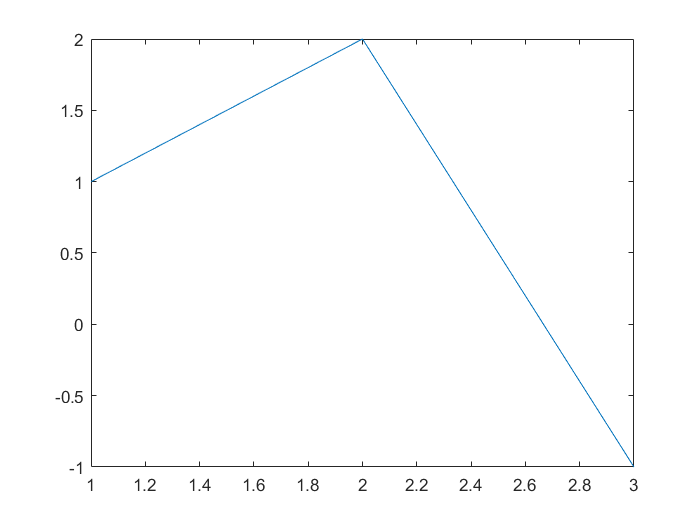


lst{end + 1} = -1;
x = 1 : numel(lst);

plot(x, cell2mat(lst));

move_setControlContinuousFwd
move_setControlContinuousBkwd
move_setNSteps(amc, axis, backwards, nSteps);
control_setControlAmplitude     % in mV
control_setControlFrequency   % in mHz
control_setControlMove    % true or false to move to set pos
setControlTargetRange    % set the range to be in target range
setSensorEnabled       % true and false to turn on and off 
getControlTargetPosition   % returns in nm
getPosition    % returns in nm
performNSteps    % false triggers one forward step, true one backwards step
setControlTargetPosition    % set abs target in nm
setNSteps    % backward, step
setSingleStep   % 
getControlTargetPosition   % gets the target position 